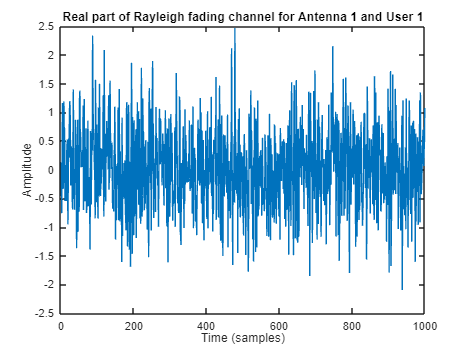

% Simulation parameters
M = 128;       % Number of antennas at HMIMO base station
K = 5;        % Number of users
min_radius = 5;   % Minimum distance of users from HMIMO base station (in meters)
radius = 100;      % Max distance of users from HMIMO base station (in meters)
nSamples = 1000;    % Number of time samples to simulate time-varying channels
SNR_dB = 10;       % Signal-to-noise ratio in dB
SNR = 10^(SNR_dB/10); % Linear scale SNR
fD = 100;           % Maximum Doppler frequency (Hz) for Rayleigh fading (user mobility)
Ts = 1e-3;         % Sampling interval in seconds

% HMIMO Base Station at fixed location (0, 0)
hmimo_x = 0;
hmimo_y = 0;

% Randomly generate user positions with constraints (min and max distances)
user_angles = 2 * pi * rand(K, 1);              % Random angle for each user
user_distances = min_radius + (radius - min_radius) * rand(K, 1); % Ensure users stay between min and max radius

% Convert to cartesian coordinates
user_x = user_distances .* cos(user_angles);
user_y = user_distances .* sin(user_angles);

% Pre-allocate memory for the Rayleigh fading channel and beamforming gain
H = zeros(M, K, nSamples); % Channel matrix for MxK for each time sample
beamforming_gain = zeros(K, nSamples); % Beamforming gain for each user

% Rayleigh fading with Doppler (Jakes model inspired)
for timeIdx = 1:nSamples
    for userIdx = 1:K
        % Generate Rayleigh fading channel for each user (Jakes model inspired)
        h_real = sqrt(0.5) * randn(M, 1); % Real part
        h_imag = sqrt(0.5) * randn(M, 1); % Imaginary part
        
        % Combine to form complex Gaussian channel coefficients (Rayleigh fading)
        H(:, userIdx, timeIdx) = h_real + 1i * h_imag;
    end
end

figure;
plot(squeeze(real(H(1,1,:))));
title('Real part of Rayleigh fading channel for Antenna 1 and User 1');
xlabel('Time (samples)');
ylabel('Amplitude');

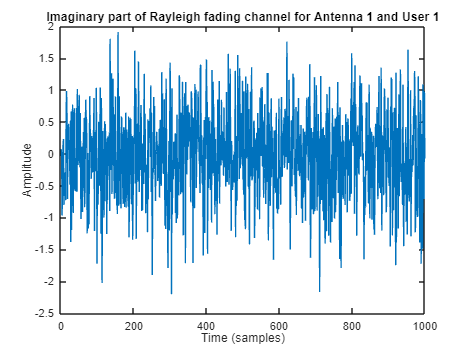


figure;
plot(squeeze(imag(H(1,1,:))));
title('Imaginary part of Rayleigh fading channel for Antenna 1 and User 1');
xlabel('Time (samples)');
ylabel('Amplitude');

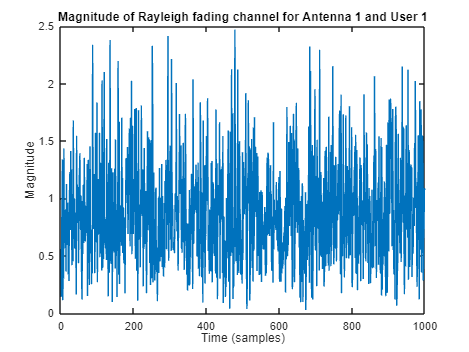


figure;
plot(squeeze(abs(H(1,1,:))));
title('Magnitude of Rayleigh fading channel for Antenna 1 and User 1');
xlabel('Time (samples)');
ylabel('Magnitude');

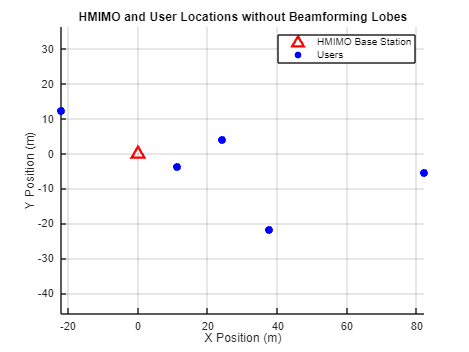


figure;
hold on;
plot(hmimo_x, hmimo_y, 'r^', 'MarkerSize', 10, 'LineWidth', 2); % HMIMO base station
scatter(user_x, user_y, 50, 'b', 'filled'); % Users positions
legend('HMIMO Base Station', 'Users');
title('HMIMO and User Locations without Beamforming Lobes');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis equal;
grid on;

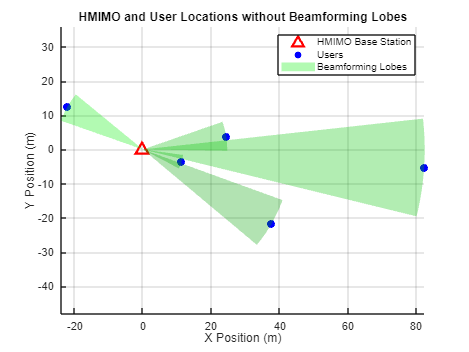


beamwidth_deg = 20;
beamwidth_rad = deg2rad(beamwidth_deg);

for timeIdx = 1:nSamples
    cla;
    plot(hmimo_x, hmimo_y, 'r^', 'MarkerSize', 10, 'LineWidth', 2);
    scatter(user_x, user_y, 50, 'b', 'filled');
    
    for userIdx = 1:K
        h_k = H(:, userIdx, timeIdx);
        w_k = h_k / norm(h_k);       
        beamforming_gain(userIdx, timeIdx) = abs(h_k' * w_k)^2;
        
        % Calculate the angle between HMIMO and user
        dx = user_x(userIdx) - hmimo_x;
        dy = user_y(userIdx) - hmimo_y;
        angle_to_user = atan2(dy, dx); 
        
        % Define the sector (beam lobe) parameters
        theta_start = angle_to_user - beamwidth_rad/2;
        theta_end = angle_to_user + beamwidth_rad/2;
        r_max = sqrt(dx^2 + dy^2); 
        
        % Create the beam lobe as a sector
        theta = linspace(theta_start, theta_end, 100);
        r = linspace(0, r_max, 50); 
        [Theta, R] = meshgrid(theta, r);
        [X, Y] = pol2cart(Theta, R);
        
        % Shift the beam lobe to HMIMO position
        X = X + hmimo_x;
        Y = Y + hmimo_y;
        
        % Beam lobe color intensity proportional to beamforming gain
        beam_intensity = beamforming_gain(userIdx, timeIdx);
        beam_color = [0, 1, 0] * min(1, beam_intensity / max(beamforming_gain(:)));
        
        % Plot the beam lobe
        surf(X, Y, zeros(size(X)), 'FaceColor', beam_color, 'EdgeColor', 'none', 'FaceAlpha', 0.3);
    end
    
    % Update plot with legend
    legend('HMIMO Base Station', 'Users', 'Beamforming Lobes');
    view(2);
    drawnow; 
    pause(0.05);
end